# Visualises/plots time series for node pressures, water velocity and water flow.

## This example contains: 

- Load a network. 

- Hydraulic analysis using ENepanet binary file. 

- Change time-stamps from seconds to hours. 

- Plot node pressures for specific nodes. 

- Plot water velocity for specific links. 

- Plot water flow for specific links. 

- Unload library.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


##  Load a network

d = epanet('Net1.inp', 'loadfile');

EPANET version {20303} loaded (EMT version {v2.3.03 - Last Update: 02/01/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Hydraulic analysis using ENepanet binary file (This function ignore events)

hyd_res = d.getComputedHydraulicTimeSeries('time', 'pressure', 'flow', 'velocity');

## Change time-stamps from seconds to hours

hrs_time = hyd_res.Time/3600;

## Plot node pressures for specific nodes 

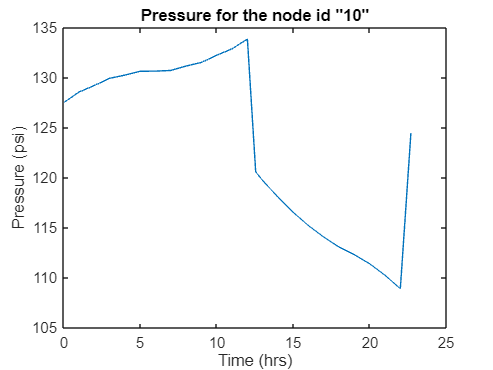

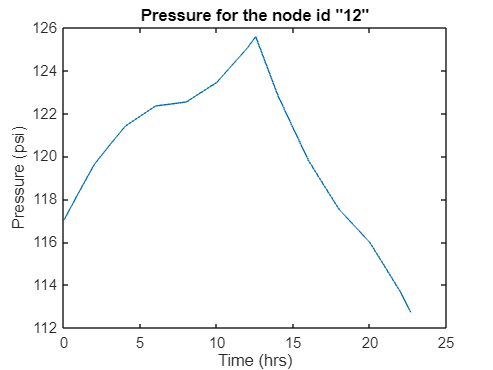

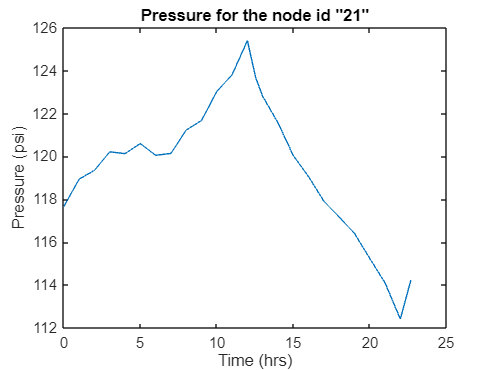

node_indices = [1, 3, 5];
node_names = d.getNodeNameID(node_indices);
units = d.getUnits;
for i=node_indices
    figure;
    plot(hrs_time, hyd_res .Pressure(:,i));
    title(['Pressure for the node id "', d.getNodeNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Pressure (', units.NodePressureUnits,')'])
end

## Plot water velocity for specific links

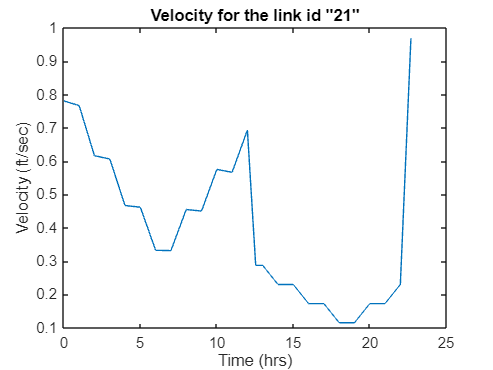

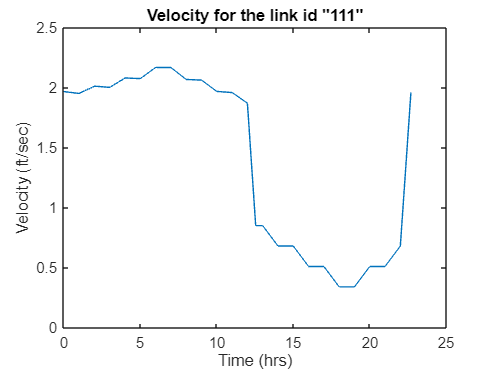

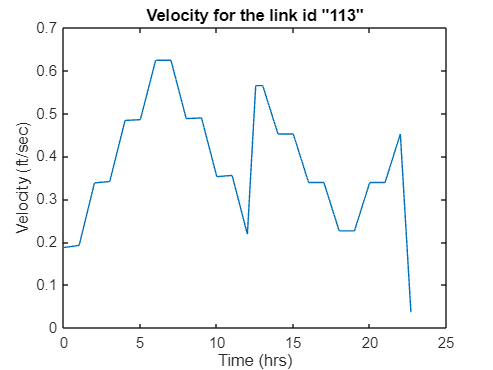

link_indices = [4, 8, 10];
link_names = d.getNodeNameID(link_indices);
for i=link_indices
    figure;
    plot(hrs_time, hyd_res.Velocity(:,i));
    title(['Velocity for the link id "', d.getLinkNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Velocity (', units.LinkVelocityUnits,')'])
end

## Plot water flow for specific links

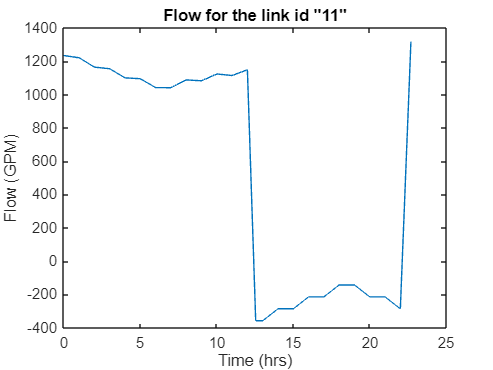

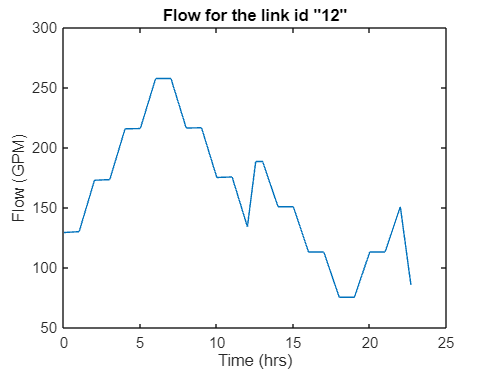

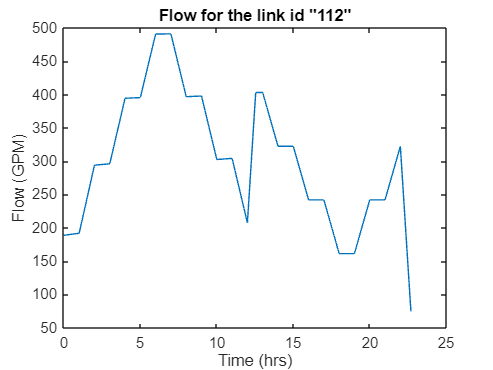

link_indices = [2, 3, 9];
for i=link_indices
    figure;
    plot(hrs_time, hyd_res.Flow(:,i));
    title(['Flow for the link id "', d.getLinkNameID{i},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Flow (', units.LinkFlowUnits,')'])
end

## Unload library.

d.unload

EPANET Class is unloaded
